R1= 10000;
R2=10000;
C1=220*10^(-6);
C2=100*10^(-6);

syms I1 I2 Vin s
I=[I1 ;I2];
A=[ R1+1/(s*C1), -1/(s*C1) ; -1/(s*C1) , R2+ 1/(s*C1)+1/(s*C2)];
V=[Vin; 0];

Result=inv(A)*V;
Vout=Result(2)/(s*C2);
Gs=Vout/Vin

$$Gs = \frac{5}{11\,s^{2}+21\,s+5}$$

s=tf('s');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

G_s=5/(11*s^2+21*s+5);

%Controllers;
Ka=2.5;
Kp=2.8;
Ki=0.8;
%Discrete-time Transfer Function
G_sd=c2d(G_s, 0.1, 'zoh')

G_sd =
 
  0.002134 z + 0.002002
  ----------------------
  z^2 - 1.822 z + 0.8262
 
Sample time: 0.1 seconds
Discrete-time transfer function.



C_P=Ka

C_P = 2.5000

PI=Kp+Ki/s;
C_PI=c2d(PI, 0.1, 'zoh')

C_PI =
 
  2.8 z - 2.72
  ------------
     z - 1
 
Sample time: 0.1 seconds
Discrete-time transfer function.



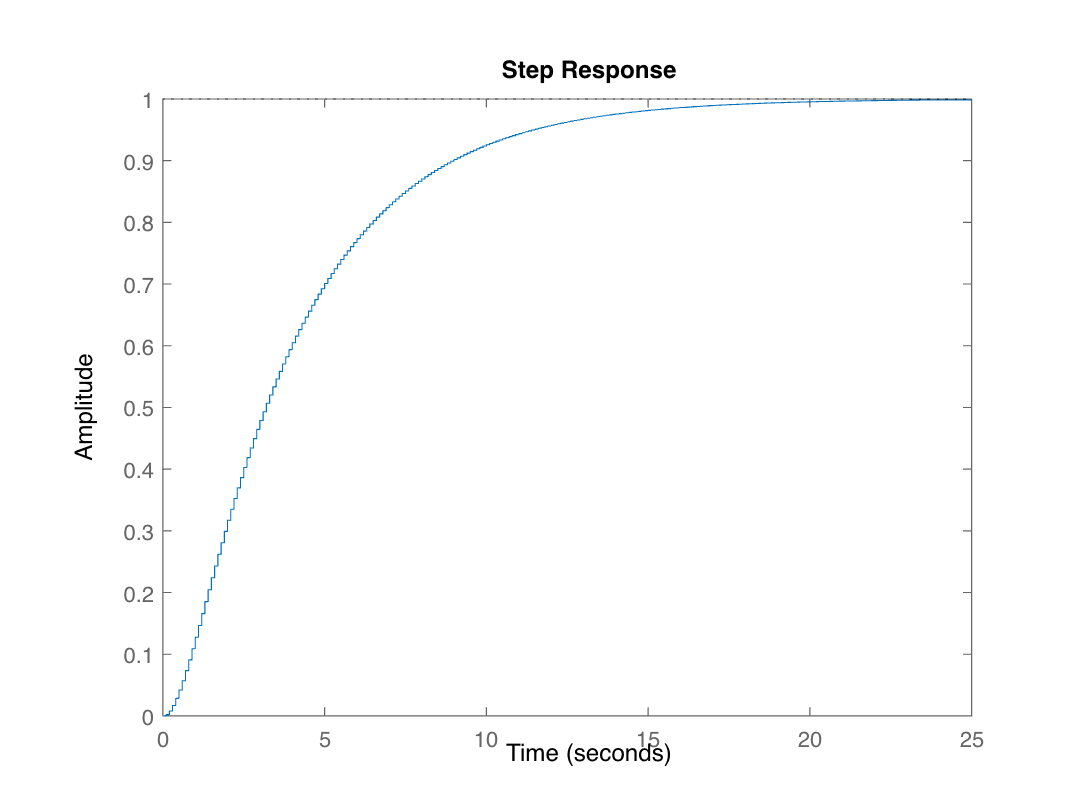


%Graffics
step(G_sd)

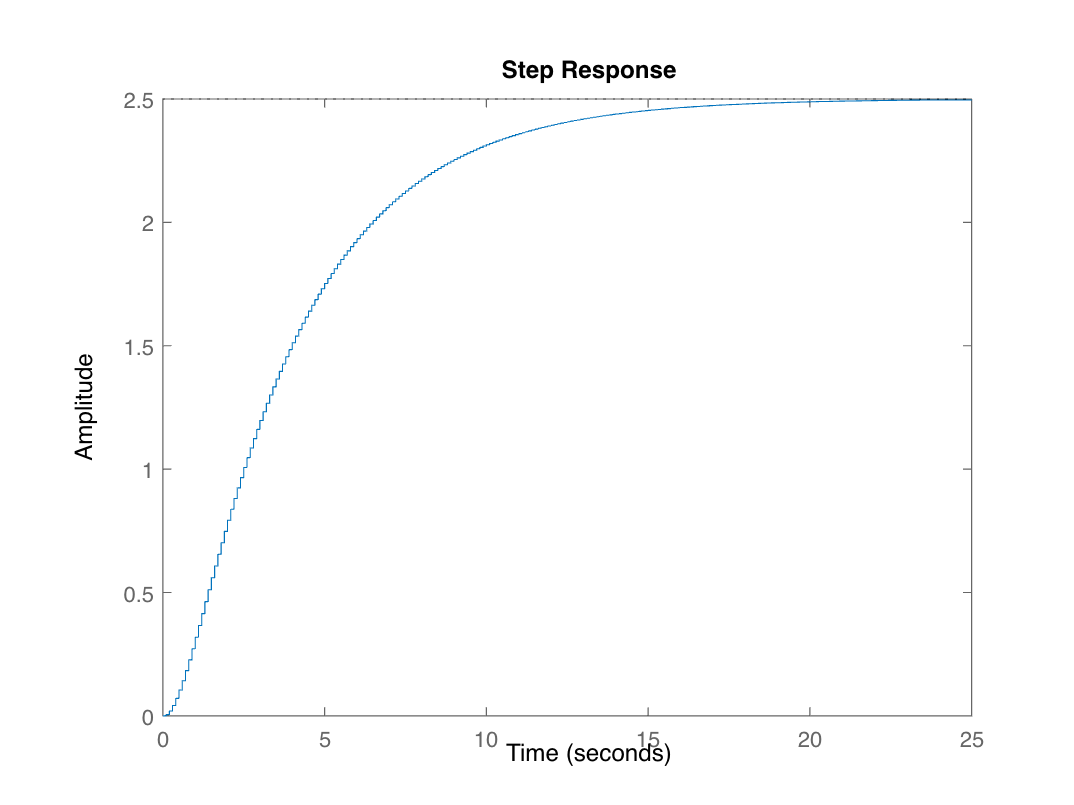

step(G_sd*C_P)

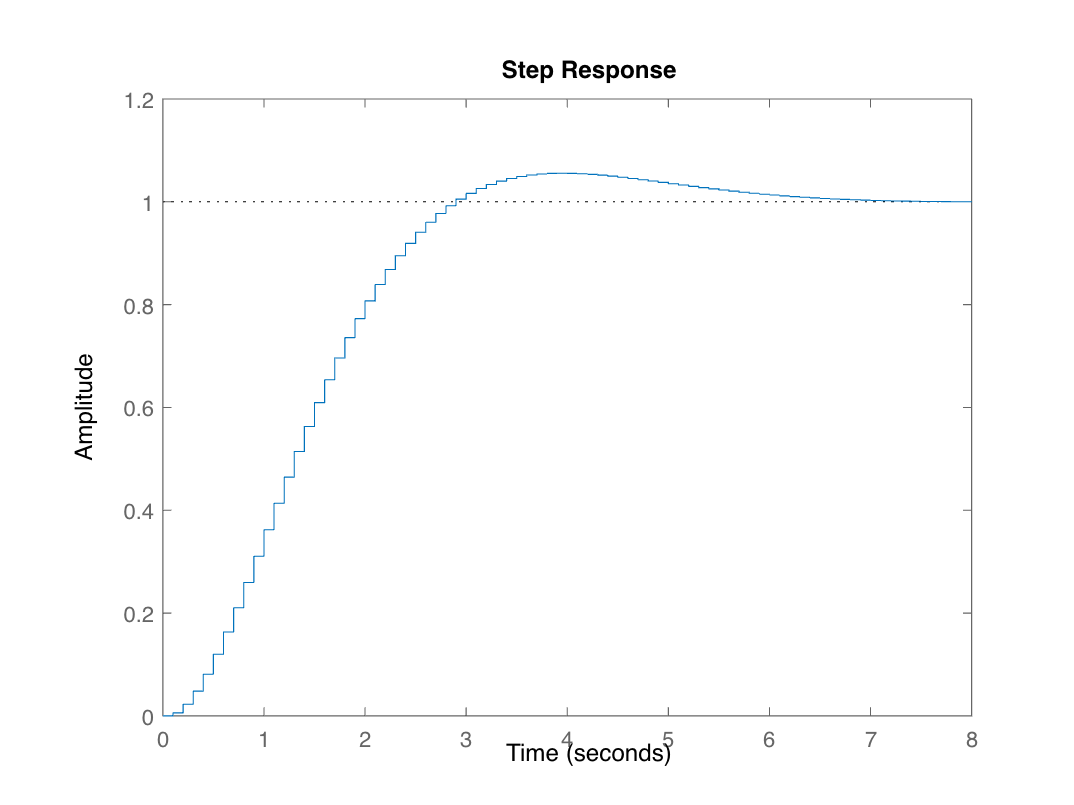

step(feedback(G_sd*C_PI,1))